## H1 versió automàtica

1.

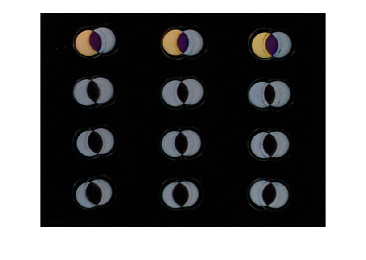

A = double(imread("Blispac1.tif"))/255;
B = double(imread("Blispac2.tif"))/255;
D = abs(A - B);
imshow(D)

2.

Ag = rgb2gray(A);
X = medfilt2(Ag,[5,5])>0.5;
X = bwareafilt(X,12);
T = regionprops('table',X,'Centroid'); % cercles centroids
LT = min(T.Centroid);  % coordenades del centre de la pastilla superior esquerre
RB = max(T.Centroid);  % inferior dreta
LB = [LT(1) RB(2)];    % inferior esquerre
RT = [RB(1) LT(2)];    % superior dreta

M = [LT; RB; LB; RT];  % matriu amb els quatre punts fixes

Bg = rgb2gray(B);
Y = medfilt2(Bg,[5,5])>0.5;
Y = bwareafilt(Y,12);
S = regionprops('table',Y,'Centroid'); % cercles centroids
LT = min(S.Centroid);  % coordenades del centre de la pastilla superior esquerre
RB = max(S.Centroid);  % inferior dreta
LB = [LT(1) RB(2)];    % inferior esquerre
RT = [RB(1) LT(2)];    % superior dreta

N = [LT; RB; LB; RT];  % matriu amb els quatre punts a moure

tform = fitgeotrans(N,M,'similarity');

3.

B_aligned = imwarp(B,tform,'Outputview',imref2d(size(B)));

4.

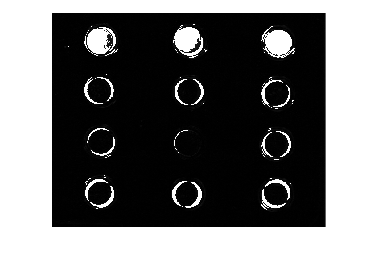

D = abs(A-B_aligned);
Dg = rgb2gray(D);
Dg(Dg>0.1) = 1;
imshow(Dg)